# Implementing ROC curves

You're working for a web applications company who use machine learning in many of their projects and have in-house implementations of a number of different classifiers and evaluation methods. At the moment all staff are using confusion matrices when training their classifiers and tuning hyperparameters. Your boss has asked you to implement a new Receiver Operating Characteristic (ROC) curve function which will use both the predicted class labels and likelihood scores from any given classifier in order to generate an ROC curve. 

As a first step, you've agreed to implement your basic approach in Matlab and check you can exactly recreate results from Matlab's built-in `perfcurve()` function. (You can then port your solution over to another language once you're certain your approach is sound.) Your boss has provided you with some pre-trained classifiers and data with which you can test the behaviour of the built-in `perfcurve()` function:

clear all;

% load some 2 classifiers and some data to help us:
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

% add as many lines of code as you need below:
%predicting labels for NaiveBayes and DecisionTree
[predictions_nb,score_nb] = predict(m_nb, test_examples);
[predictions_dt,score_dt] = predict(m_dt,test_examples);
%calculating likelihood and generating confusion matrix
[c_nb,order_nb]=confusionmat(test_labels,predictions_nb);
p_nb = sum(diag(c_nb)) / sum(c_nb(1:1:end));
[c_dt,order_dt]=confusionmat(test_labels,predictions_dt);
p_dt = sum(diag(c_dt)) / sum(c_dt(1:1:end));
%TPR for malignant as positive class
tpr_nb=c_nb(2,2)/sum(c_nb(2,:))

tpr_nb = 0.9298

tpr_dt=c_dt(2,2)/sum(c_dt(2,:))

tpr_dt = 0.9123

%FPR for malignant as positive class
fpr_nb=c_nb(1,2)/sum(c_nb(1,:))

fpr_nb = 0.0235

fpr_dt=c_dt(1,2)/sum(c_dt(1,:))

fpr_dt = 0.0353

%generating ROC curve
[x,y] = perfcurve(test_labels, score_nb(:,2), 'Malignant');
[x1,y1] = perfcurve(test_labels, score_dt(:,2), 'Malignant');

[x2,y2] = my_roc(test_labels, score_nb(:,2), 'Malignant');

thresholds =     1.0000    0.9990    0.9980    0.9970    0.9960    0.9950    0.9940    0.9930    0.9920    0.9910    0.9900    0.9890    0.9880    0.9870    0.9860    0.9850    0.9840    0.9830    0.9820    0.9810    0.9800    0.9790    0.9780    0.9770    0.9760    0.9750    0.9740    0.9730    0.9720    0.9710    0.9700    0.9690    0.9680    0.9670    0.9660    0.9650    0.9640    0.9630    0.9620    0.9610    0.9600    0.9590    0.9580    0.9570    0.9560    0.9550    0.9540    0.9530    0.9520    0.9510


[x3,y3] = my_roc(test_labels, score_dt(:,2), 'Malignant');

thresholds =     1.0000    0.9990    0.9980    0.9970    0.9960    0.9950    0.9940    0.9930    0.9920    0.9910    0.9900    0.9890    0.9880    0.9870    0.9860    0.9850    0.9840    0.9830    0.9820    0.9810    0.9800    0.9790    0.9780    0.9770    0.9760    0.9750    0.9740    0.9730    0.9720    0.9710    0.9700    0.9690    0.9680    0.9670    0.9660    0.9650    0.9640    0.9630    0.9620    0.9610    0.9600    0.9590    0.9580    0.9570    0.9560    0.9550    0.9540    0.9530    0.9520    0.9510


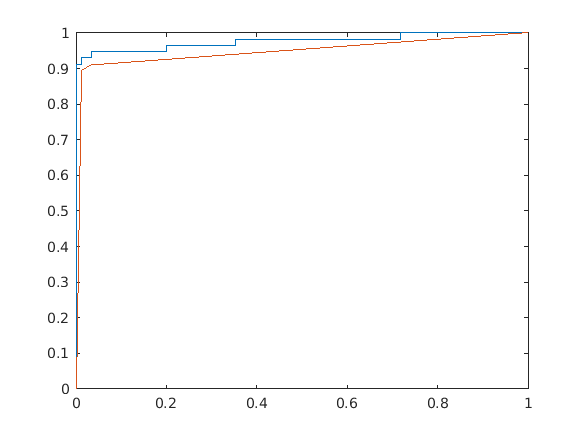

%plotting the ROC curves on the same graph
plot(x,y)
hold on
plot(x1,y1)
hold off

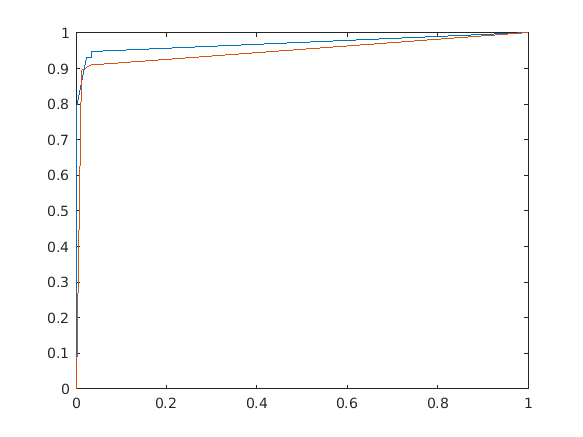


plot(x2,y2)
hold on
plot(x3,y3)
hold off

Your boss has also provided you with some skeleton code for a `my_roc()` function (below) which roughly sketches what they expect your solution to look like. Your task is to get this function working correctly. Marks are available for:

- **In the code listing above**: Using `perfcurve()` to generate an ROC curve for each classifier, taking "Malignant" as the positive class, and plotting them together on a single graph with a legend and labelled axes [4 marks]

- **In the **`my_roc()`** function below**: Deciding the likelihood thresholds over which the outer for loop in `my_roc()` should iterate [4 marks]

- **In the **`my_roc()`** function below**: Updating the `tn`, `fp`, `fn` and `tp` count variables as appropriate inside the inner loop [4 marks]

- **In the **`my_roc()`** function below**: Calculating the resulting True Positive Rate and False Positive Rate and storing both results [4 marks]

- **In the code listing above**: Convincing yourself that `my_roc()` is working as it should by plotting a new figure to compare with the one you generated in part 1 [4 marks]

[20 marks]

function [fprs, tprs] = my_roc(labels, scores, posclass)
    
    % start off arrays to hold the True Positive and False Positive Rates:
    tprs = 0;
    fprs = 0;

    % determine the name of the non-positive class:
    all_labels = unique(labels);
    other = setdiff(all_labels, posclass);
    
    thresholds = [];
    % Decide the likelihood thresholds over which we should loop:
    %thresholds = ...
    thresholds = max(scores):-0.001:min(scores)
    % for every threshold value:
    for i = 1:1:length(thresholds)
        
        % set the new threshold:
        threshold = thresholds(i);
        
        % initialise count variables for:
        tn = 0; % True Negatives
        fp = 0; % False Positives
        fn = 0; % False Negatives
        tp = 0; % True Positives
        
        % for every classification:
        for j = 1:length(scores)
            
            % is the associated classification score greater than the current threshold
            if scores(j) >= threshold
                % was the example truly a member of the positive class?
                if labels(j) == posclass
                    % update the appropriate count variable:
                    tp=tp+1;
                else
                    
                    % update the appropriate count variable:
                    fp=fp+1;
                end
            else
                % was the example truly a member of the other class?
                if labels(j) == other
                    % update the appropriate count variable:
                    tn=tn+1;
                else
                    % update the appropriate count variable:
                    fn=fn+1;
                end
            end
            
        end
        
        % calculate the updated True Positive and False Positive Rates and
        % store them:
        tprs(end+1) = tp/(tp+fn);
        fprs(end+1) = fp/(fp+tn);
        
    end
    
end